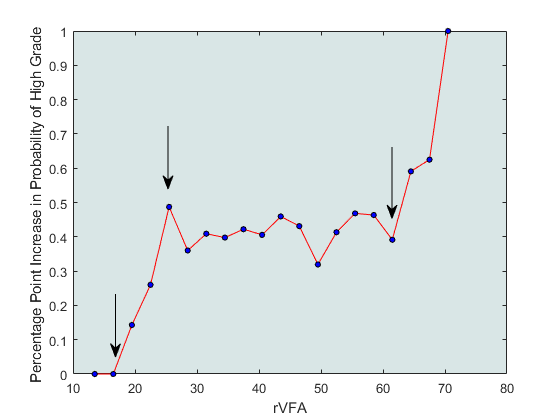

clear
clc

load('BingliFatAnalysis.mat')
FTT = table2array(BingliFatData);
FTT(:,5) = 100*FTT(:,3)./FTT(:,2);
FTT(:,4) = FTT(:,2) - FTT(:,3);
% P = FTT(:,6)==1;
% PP = FTT(P,:);
% N = FTT(:,6)==0;
% NN = FTT(N,:);
clear BingliFatData, clear rows_without_nan
%% firstly, we donot choose the data and look at how the result is.

rVF = FTT(:,5);
lab = FTT(:,6);

minvalue = min(rVF); 
maxvalue = max(rVF);

% step = 0.2;
% starter = 0;
% Fasheng = [];
% Points = [];
% while starter < 6
%     lower = starter;
%     upper = starter + step;
%     in_range = (rVF>=lower)&(rVF<upper);
%     elements = lab(in_range);
%     ratio = sum(elements)/length(elements);
%     Fasheng = [Fasheng ratio];
%     Points = [Points mean([lower,upper])];
%     starter = starter + step;
%     
% end
% figure
% plot(Points, Fasheng)

% step = 1;
% starter = 0;
% Fasheng = [];
% Points = [];
% while starter < 70
%     lower = starter;
%     upper = starter + step;
%     in_range = (rVF>=lower)&(rVF<upper);
%     elements = lab(in_range);
%     ratio = sum(elements)/length(elements);
%     Fasheng = [Fasheng ratio];
%     Points = [Points mean([lower,upper])];
%     starter = starter + step;
%     
% end
% figure
% plot(Points, Fasheng)

% step = 2;
% starter = 0;
% Fasheng = [];
% Points = [];
% while starter < 70
%     lower = starter;
%     upper = starter + step;
%     in_range = (rVF>=lower)&(rVF<upper);
%     elements = lab(in_range);
%     ratio = sum(elements)/length(elements);
%     Fasheng = [Fasheng ratio];
%     Points = [Points mean([lower,upper])];
%     starter = starter + step;
%     
% end
% figure
% plot(Points, Fasheng)
% 
% 
step = 3;
starter = 0;
Fasheng = [];
Points = [];
while starter < 70
    lower = starter;
    upper = starter + step;
    in_range = (rVF>=lower)&(rVF<upper);
    elements = lab(in_range);
    ratio = sum(elements)/length(elements);
    Fasheng = [Fasheng ratio];
    Points = [Points mean([lower,upper])];
    starter = starter + step;
    
end
fig3step=figure;
plot(Points, Fasheng, 'r-o', 'MarkerSize', 4, 'MarkerFaceColor', 'b', 'MarkerEdgeColor', 'k');
xlabel('rVFA');
ylabel('Percentage Point Increase in Probability of High Grade ');
       set(gcf, 'Color', [1 1 1]); % 设置图形窗口背景为bai色
       set(gca, 'Color', [0.85, 0.9, 0.9]); % 设置坐标轴背景为qianhuilan色
hold on;
% quiver(3, 0.5, 0, -0.5, 0, 'Color', 'r', 'LineWidth', 2); % 起点 (5, 0.5)，方向向量 (2, 0.5)
%  quiver(16.5, 0.2, 0, -0.3, 'AutoScale',false,  'LineWidth', 2);
   % 添加箭头
   annotation('arrow', [16.5/80, 16.5/80], [0.3, 0.15]); % [起点X, 终点X], [起点Y, 终点Y]
   % 注意：annotation 的坐标是归一化的，范围是 [0, 1]，其中 (0, 0) 是左下角，(1, 1) 是右上角。
   annotation('arrow', [56/80, 56/80], [0.65, 0.48]); % [起点X, 终点X], [起点Y, 终点Y]
   annotation('arrow', [16.5/80, 16.5/80], [0.3, 0.15]); % [起点X, 终点X], [起点Y, 终点Y]
   annotation('arrow', [24/80, 24/80], [0.7, 0.55]);
hold off;

 exportgraphics(fig3step, 'Figure3_2step3AgeFat.tif','resolution',300);

% 
% 
% 
% 
% step = 4;
% starter = 0;
% Fasheng = [];
% Points = [];
% while starter < 70
%     lower = starter;
%     upper = starter + step;
%     in_range = (rVF>=lower)&(rVF<upper);
%     elements = lab(in_range);
%     ratio = sum(elements)/length(elements);
%     Fasheng = [Fasheng ratio];
%     Points = [Points mean([lower,upper])];
%     starter = starter + step;
% end
% fig4step=figure;
% plot(Points, Fasheng, 'r-o', 'MarkerSize', 4, 'MarkerFaceColor', 'b', 'MarkerEdgeColor', 'k');
% xlabel('rVFA');
% ylabel('Percentage Point Increase in Probability of HighGrade ');
%        set(gcf, 'Color', [1 1 1]); % 设置图形窗口背景为bai色
%        set(gca, 'Color', [0.85, 0.9, 0.9]); % 设置坐标轴背景为qianhuilan色
% hold on;
% % quiver(3, 0.5, 0, -0.5, 0, 'Color', 'r', 'LineWidth', 2); % 起点 (5, 0.5)，方向向量 (2, 0.5)
%   quiver(23, 0.5, 0, -0.1,'k', 'filled', 'AutoScale','off',  'LineWidth', 2);
% hold off;
% 
% exportgraphics(fig4step, 'Figure3step4AgeFat.tif','resolution',300);



% step = 5;
% starter = 0;
% Fasheng = [];
% Points = [];
% while starter < 70
%     lower = starter;
%     upper = starter + step;
%     in_range = (rVF>=lower)&(rVF<upper);
%     elements = lab(in_range);
%     ratio = sum(elements)/length(elements);
%     Fasheng = [Fasheng ratio];
%     Points = [Points mean([lower,upper])];
%     starter = starter + step;
%     
% end
% 
% figure
% plot(Points, Fasheng)





%%%%  make the vf---tf  matrix ------- the 3 coulmn is VF, 2 column is TF
% 
% minVF = min(FTT(:,3)); maxVF = max(FTT(:,2));
% minTF = min(FTT(:,2)); maxTF = max(FTT(:,2));
% 
% stepVF = (maxVF - minVF)/20;
% stepTF = (maxTF - minTF)/20;
% 
% VFpoints = (minVF+stepVF/2):stepVF:(maxVF-stepVF/2);
% TFpoints = (minTF+stepTF/2):stepTF:(maxTF-stepTF/2);
% 
% % Matrix = (sort(VFpoints,'descend'))' * (1./TFpoints);
% Matrix = 100*repmat(VFpoints,20,1)./repmat(TFpoints',1,20);





% 
% %%%%%%%%%%%%%%%    smoothing the risk surface %%%%%%%%%%%%%%%%%%%%%%%%%%%
% % 定义 Logit 函数
% logitFun = @(b,x) 1 ./ (1 + exp(-(b(1) + b(2) .* x)));
% 
% Fasheng(1:2)=[0 0];
% % 初始参数估计值
% b0 = [0, 0]; % 初始值可以根据实际情况调整
% 
% % 拟合模型
% options = optimoptions('lsqcurvefit', 'Display', 'off'); % 关闭优化过程的显示
% b_fit = lsqcurvefit(logitFun, b0, Points, Fasheng, [], [], options);
% 
% % 输出拟合结果
% disp('拟合的参数：');
% disp(b_fit);
% 
% % 绘制原始数据点
% figure;
% scatter(Points, Fasheng, 'filled');
% hold on;
% 
% % 绘制拟合曲线
% x_fit = linspace(min(Points), max(Points), 100); % 生成用于绘制曲线的 x 值
% y_fit = logitFun(b_fit, x_fit); % 计算对应的 y 值
% plot(x_fit, y_fit, 'r-', 'LineWidth', 2);
% 
% % 添加图例和标题
% legend('原始数据', '拟合曲线');
% xlabel('x');
% ylabel('y');
% title('Logit 函数拟合');
% hold off;

% Risk = zeros(20,20);
% for i=1:20
%     for j=1:20
%         rvf=Matrix(i,j);
%         if rvf>70
%             Risk(i,j)=1;
%         else
%         differences = abs(Points - rvf);
%         [~, index] = min(differences);
%         Risk(i,j) = Fasheng(index);   
%         end
% 
%     end
% end

% Risk = zeros(20,20);
% for i=1:20
%     for j=1:20
%         rvf=Matrix(i,j);
% 
%         Risk(i,j) = logitFun(b_fit, rvf); % 计算对应的 y 值);   
%         
% 
%     end
% end
% 
% mesh(VFpoints, TFpoints,Risk)







% %%%%%%%%%%%%%%%%%%%%%  对相应长度区间进行等比例采样（用欠采样！！！不动数据本身） %%%%%%%%%%%%% 
% %%%%%%%%%%%%%%%%%%%%%  在整个数据集上的性能 %%%%%%%
% LowYuzhi = 23;
%  Rangeh = (lab==1);
% Rangel = (lab==0);
%  index = 1:1122;
% % 
%  ol = index(Rangel);
%  p = randperm(length(ol));
%  yaode = p(1:sum(Rangeh));
% % 
%  yaol = ol(yaode);
%  yaoh = index(Rangeh);
% % 
%  data = [FTT(yaoh',:) ; FTT(yaol',:)];
% 
% %%%% Computing the ROC area of  the Logistic Regression 
% % data = FTT;
% mdl = fitglm(data(:,(1:5)),data(:,6),'Distribution','binomial','Link','logit');
% 
% scores = mdl.Fitted.Probability;
% learnedlab = (scores>0.5);
% acc = sum(learnedlab==data(:,6))/length(data(:,6));
% 
% [X,Y,T,auc] = perfcurve(data(:,6), scores,'1');
% 
% plot(X,Y)
% xlabel('False positive rate') 
% ylabel('True positive rate')
% title('ROC for Classification by Logistic Regression')
% 
% 
% [X1,Y1,T1,AUC] = perfcurve(data(:,6),mdl.Fitted.Probability,...
%     '1','NBoot',1000,'BootType', 'bca');
% %% acc is unchanged because the output scores are definite
% % % 在 MATLAB 中，perfcurve 函数用于计算分类器性能曲线（如 ROC 曲线）及其相关指标（如 AUC）。根据搜索结果，perfcurve 的输出变量及其含义如下：
% % % X：ROC 曲线上的假正率（False Positive Rate, FPR）值。
% % % Y：ROC 曲线上的真正率（True Positive Rate, TPR）值。
% % % T：用于计算 X 和 Y 的分类器得分阈值。
% % % AUC：ROC 曲线下的面积（Area Under the Curve），用于评估分类器的整体性能。
% % % 如果未计算置信区间，AUC 是一个标量值。
% % % 如果计算了置信区间（如通过 Bootstrap 方法），AUC 是一个 3×1 的向量，包含均值、置信区间下限和上限。
% % % OPTROCPT：ROC 曲线上的最优操作点（Optimal Operating Point），返回一个 1×2 的数组，包含最优点的 FPR 和 TPR。
% % % SUBY：负类别的 Y 值。如果指定了多个负类别，SUBY 是一个矩阵，每列对应一个负类别。
% % % SUBYNAMES：负类别的名称，返回一个单元数组，包含负类别的标签。
% % 
% % figure()
% % errorbar(X1(:,1),Y1(:,1),Y1(:,1)-Y1(:,2),Y1(:,3)-Y1(:,1));
% % xlim([-0.02,1.02]); ylim([-0.02,1.02]);
% % xlabel('False positive rate')
% % ylabel('True positive rate')
% % title('ROC Curve with Pointwise Confidence Bounds')
% % legend('PCBwTA','Location','Best')
% % 
% % % % 如果用交叉验证的方法，三种AUC，留一法的是平均这个不行，得是我原来那个自己的myperfcurve.m ; holdout
% % % 可以是平均可以是自己的perfcurve. 那个多折的取平均的总觉得不是个事！！！ 看看matlab的交叉验证命令吧，咋弄的？
% % 
% % 
% % 
% % 
% % %%%%%%%%%%%%%%%%%%%%%  对相应长度区间进行等比例采样（用欠采样！！！不动数据本身） %%%%%%%%%%%%% 
% % %%%%%%%%%%%%%%%%%%%%%  在整个数据集上的  中间段的（23---65）    性能 %%%%%%%
% % LowYuzhi = 23;
%  Rangeh = (lab==1)&(rVF>20)&(rVF<30);
% Rangel = (lab==0)&(rVF>20)&(rVF<30);
%  index = 1:1122;
% % 
%  ol = index(Rangel);
%  p = randperm(length(ol));
%  yaode = p(1:sum(Rangeh));
% % 
%  yaol = ol(yaode);
%  yaoh = index(Rangeh);
% % 
%  data = [FTT(yaoh',:) ; FTT(yaol',:)];
% 
% %%%% Computing the ROC area of  the Logistic Regression 
% % data = FTT;
% mdl = fitglm(data(:,5),data(:,6),'Distribution','binomial','Link','logit');
% 
% scores = mdl.Fitted.Probability;
% learnedlab = (scores>0.5);
% midacc = sum(learnedlab==data(:,6))/length(data(:,6));
% 
% [X,Y,T,midauc] = perfcurve(data(:,6), scores,'1');
% 
% 
% 
% 
% 
% 
% 
% 
% 
% %%%%%%%%%%%%%%%%%%%%%  对相应长度区间进行等比例采样（用欠采样！！！不动数据本身） %%%%%%%%%%%%% 

% LowYuzhi = 22;
% lowRangeh = (rVF<LowYuzhi)&(lab==1);
% lowRangel = (rVF<LowYuzhi)&(lab==0);
% index = 1:1122;
% 
% ol = index(lowRangel);
% p = randperm(length(ol));
% yaode = p(1:sum(lowRangeh));
% 
% yaol = ol(yaode);
% yaoh = index(lowRangeh);
% 
% data = [FTT(yaoh',:) ; FTT(yaol',:)];
% 
% %%%% Computing the ROC area of  the Logistic Regression 
% 
% mdl = fitglm(data(:,5),data(:,6),'Distribution','binomial','Link','logit');
% 
% scores = mdl.Fitted.Probability;
% learnedlab = (scores>0.5);
% Lacc = sum(learnedlab==data(:,6))/length(data(:,6));
% 
% [X,Y,T,Lauc] = perfcurve(data(:,6), scores,'1');
% 
% plot(X,Y)
% xlabel('False positive rate') 
% ylabel('True positive rate')
% title('ROC for Classification by Logistic Regression')
% 
% 
% [X1,Y1,T1,AUC] = perfcurve(data(:,6),mdl.Fitted.Probability,...
%     '1','NBoot',1000,'BootType', 'bca');
% %% acc is unchanged because the output scores are definite
% % 在 MATLAB 中，perfcurve 函数用于计算分类器性能曲线（如 ROC 曲线）及其相关指标（如 AUC）。根据搜索结果，perfcurve 的输出变量及其含义如下：
% % X：ROC 曲线上的假正率（False Positive Rate, FPR）值。
% % Y：ROC 曲线上的真正率（True Positive Rate, TPR）值。
% % T：用于计算 X 和 Y 的分类器得分阈值。
% % AUC：ROC 曲线下的面积（Area Under the Curve），用于评估分类器的整体性能。
% % 如果未计算置信区间，AUC 是一个标量值。
% % 如果计算了置信区间（如通过 Bootstrap 方法），AUC 是一个 3×1 的向量，包含均值、置信区间下限和上限。
% % OPTROCPT：ROC 曲线上的最优操作点（Optimal Operating Point），返回一个 1×2 的数组，包含最优点的 FPR 和 TPR。
% % SUBY：负类别的 Y 值。如果指定了多个负类别，SUBY 是一个矩阵，每列对应一个负类别。
% % SUBYNAMES：负类别的名称，返回一个单元数组，包含负类别的标签。
% 
% figure()
% errorbar(X1(:,1),Y1(:,1),Y1(:,1)-Y1(:,2),Y1(:,3)-Y1(:,1));
% xlim([-0.02,1.02]); ylim([-0.02,1.02]);
% xlabel('False positive rate')
% ylabel('True positive rate')
% title('ROC Curve with Pointwise Confidence Bounds')
% legend('PCBwTA','Location','Best')
% 
% % % 如果用交叉验证的方法，三种AUC，留一法的是平均这个不行，得是我原来那个自己的myperfcurve.m ; holdout
% % 可以是平均可以是自己的perfcurve. 那个多折的取平均的总觉得不是个事！！！ 看看matlab的交叉验证命令吧，咋弄的？
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% highYuzhi = 65;
% highRangeh = (rVF>highYuzhi)&(lab==1);
% highRangel = (rVF>highYuzhi)&(lab==0);
% index = 1:1122;
%  oh = index(highRangeh);
%  ol = index(highRangel);
%  p = randperm(length(oh));
%  yaode = p(1:sum(highRangel));
% yaoh = oh(yaode);
% yaol = index(highRangel);
% 
% data = [FTT(yaoh',:) ; FTT(yaol',:)];
% 
% %%%% Computing the ROC area of  the Logistic Regression 
% 
% mdl = fitglm(data(:,5),data(:,6),'Distribution','binomial','Link','logit');
% 
% scores = mdl.Fitted.Probability;
% learnedlab = (scores>0.5);
% acc = sum(learnedlab==data(:,6))/length(data(:,6));
% 
% [X,Y,T,auc] = perfcurve(data(:,6), scores,'1');
% 
% plot(X,Y)
% xlabel('False positive rate') 
% ylabel('True positive rate')
% title('ROC for Classification by Logistic Regression')
% 
% 
% [X1,Y1,T1,AUC] = perfcurve(data(:,6),mdl.Fitted.Probability,...
%     '1','NBoot',1000,'BootType', 'bca');
% %% acc is unchanged because the output scores are definite
% % 在 MATLAB 中，perfcurve 函数用于计算分类器性能曲线（如 ROC 曲线）及其相关指标（如 AUC）。根据搜索结果，perfcurve 的输出变量及其含义如下：
% % X：ROC 曲线上的假正率（False Positive Rate, FPR）值。
% % Y：ROC 曲线上的真正率（True Positive Rate, TPR）值。
% % T：用于计算 X 和 Y 的分类器得分阈值。
% % AUC：ROC 曲线下的面积（Area Under the Curve），用于评估分类器的整体性能。
% % 如果未计算置信区间，AUC 是一个标量值。
% % 如果计算了置信区间（如通过 Bootstrap 方法），AUC 是一个 3×1 的向量，包含均值、置信区间下限和上限。
% % OPTROCPT：ROC 曲线上的最优操作点（Optimal Operating Point），返回一个 1×2 的数组，包含最优点的 FPR 和 TPR。
% % SUBY：负类别的 Y 值。如果指定了多个负类别，SUBY 是一个矩阵，每列对应一个负类别。
% % SUBYNAMES：负类别的名称，返回一个单元数组，包含负类别的标签。
% 
% figure()
% errorbar(X1(:,1),Y1(:,1),Y1(:,1)-Y1(:,2),Y1(:,3)-Y1(:,1));
% xlim([-0.02,1.02]); ylim([-0.02,1.02]);
% xlabel('False positive rate')
% ylabel('True positive rate')
% title('ROC Curve with Pointwise Confidence Bounds')
% legend('PCBwTA','Location','Best')
% 
% % % 如果用交叉验证的方法，三种AUC，留一法的是平均这个不行，得是我原来那个自己的myperfcurve.m ; holdout
% % 可以是平均可以是自己的perfcurve. 那个多折的取平均的总觉得不是个事！！！ 看看matlab的交叉验证命令吧，咋弄的？